# Nonlinear - single equation 

## Problem

Solve for x, in  4.5*(x-sin(x))=8

clear all
F = inline('8-4.5*(x-sin(x))');
dF=inline('-4.5*(1-cos(x))');

x=0:0.001:10;
plot(x,F(x)); grid on


### Matlab Function


x0=2.5;
sol=fzero(F,x0)


### Numerical Programming: Bisection

%% Bisection
Nmax = 100; tol = 1e-9; ep=10;
i=0;


% Initial range
a = 2; b = 3; 
xn=(a+b)/2;        

while(i<Nmax && ep>tol)
    
    if (F(a)*F(b)>0)
        disp('Error!! Same sign!!');
        break
    end
    if (F(xn)==0) 
        break       % Exact solution found
    end
    
    % Update range a, b
    if (F(xn)*F(a)<0)
        ________;
    else
        ________;    
    end
    
    % Update xn as midpoint
    xn=_________;         
    
    ep=abs(F(xn));      
    i=i+1;
end

if (i==Nmax)
    disp('Solution did not converged within given iteration!!!');
end
disp('Solution of F(x) using Bisection:');
iter=i
sol1=xn

### Numerical Programming: Newton-rhapson

%% Newton Rhapson Method - 1
Nmax = 100; tol = 1e-9; ep=10;
i=0;

x0=2.5;
xk=x0;

while(i<Nmax && ep>tol)
    if (dF(xk)==0)
        disp('Error!! dF=0 !!');
        break
    end 
    
    % get h=f/df
    h=__________;
    % update x=x+h
    xk=_____________;   
    ep=abs(F(xk));    
    i=i+1;
end

if (i==Nmax)
    disp('Solution did not converged !!!');
end

disp('Solution of F(x) using Newton-Rahpson');
iter=i
sol2=xk


# A system of linear equation

### Newton Rhapson Method 

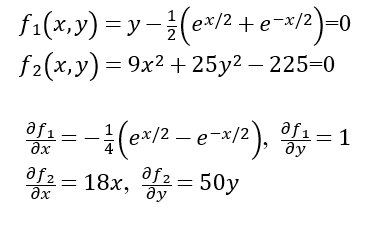    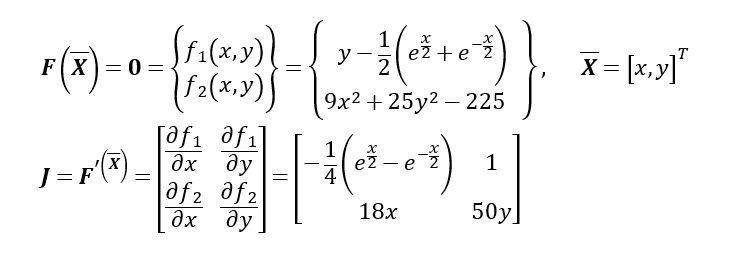

x = -4:0.1:4;
f1= 0.5*(exp(x./2) + exp(-x./2));
f2= sqrt((-9*x.^2 + 225)/25);
figure;
plot(x,f1);
hold on
plot(x,f2);

%%
F1 = @ (x,y) y - 0.5*(exp(x/2) + exp(-x/2));
F2 = @ (x,y) 9*x^2 + 25*y^2 - 225;
dF1x = @ (x) -(exp(x/2) - exp(-x/2))/4;
dF1y= @(y) 1;
dF2x = @ (x) 18*x;
dF2y = @ (y) 50*y;

FX= @(x,y) [F1(x,y);F2(x,y)];
Jacob = @ (x,y) -[dF1x(x) dF1y(y); dF2x(x) dF2y(y)];


Nmax = 100; tol = 1e-9; ep=10; i=0;

% Initialize X0=(x0,y0)
X0=[2.5; 2];

Xk=X0;
xi=Xk(1); yi=Xk(2);

while(i<Nmax && ep>tol)    
    
    % Calculate F(Xk)     
    F=______;
    
    % Calculate Jacobian matrix Jk
    J = ____________;
    
    % Solve for Hk  from J*H=F
    H=________;  % inv(A)*F
    
    % Update Xk=Xk+H
    Xk=_______;
    xi=Xk(1); yi=Xk(2);    
    
    % Check for tolerance    
    Ep=abs(FX(xi,yi));
    ep=max(Ep);
    
    fprintf('i =%d x = %-7.4f y = %-7.4f x_error= %-7.5f y_error= %-7.5f\n',i,xi,yi,Ep(1),Ep(2))
    i=i+1;
end

disp('Solution of F(x) using Newton-Rahpson');
iter=i
sol=Xk



